CA1 Report

Mohammad Farrahi                                                                                                                                           student num : 810198451  

PART1:

    Q1: Sampling frequency is defined as how many times we observe and sample, form the signal we are analyzing, per time unit. It is important to mention that sampling frequency is necessary when we are try to get fourier transform form the signal and it helps frequency axis, in transformed plot, to match to time axis in orginal plot.

    Q2: Codes for plotting signal cos(2pi * f * t)

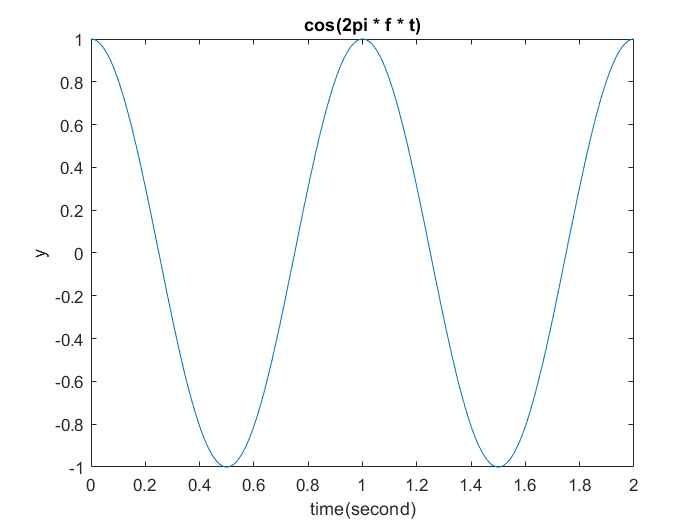

f = 1;
time_step = 0.001;
fs = 1 / time_step;
t = 0:time_step:2;
y = cos(2*pi*f*t);

plot(t, y)
title cos(2pi * f * t)
ylabel y
xlabel time(second)

    Q3: linspace(x1, x2, n) generates arrays of n points, which the space between each point is (x2 - x1) / (n - 1). Therefore linspase generates linearly spaced values.

numly(A) returns number of elements in array A.

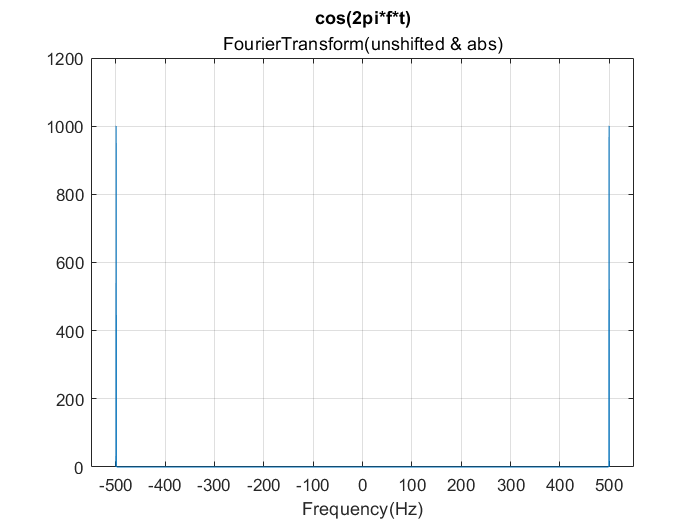

fFft = linspace(-fs/2, fs/2, numel(y));

yFft = fft(y);
plot(fFft, abs(yFft))
grid on
xlim([-550 550])
title cos(2pi*f*t) FourierTransform(unshifted & abs)
xlabel Frequency(Hz)

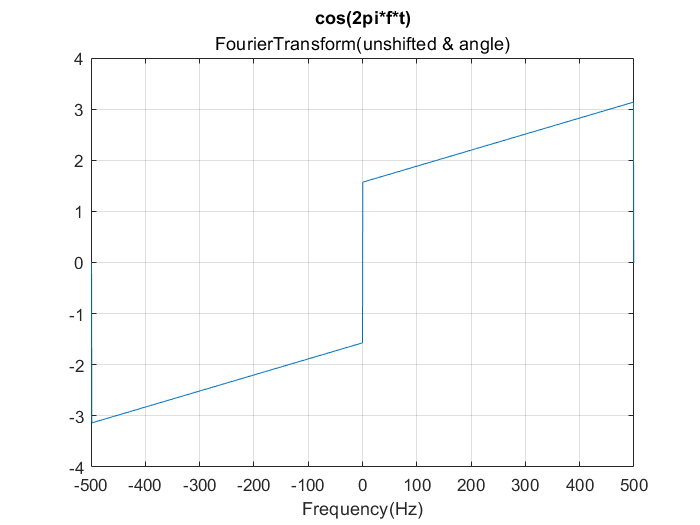


plot(fFft, angle(yFft))
grid on
title cos(2pi*f*t) FourierTransform(unshifted & angle)
xlabel Frequency(Hz)

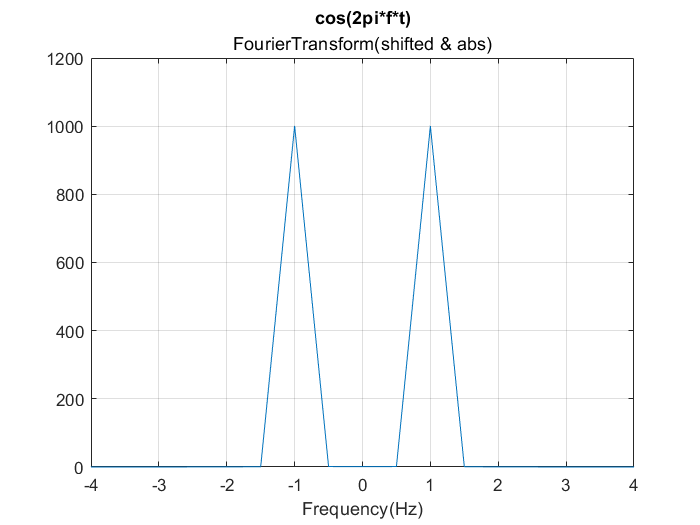


yFftshift = fftshift(yFft);
plot(fFft, abs(yFftshift))
xlim([-4 4])
grid on
title cos(2pi*f*t) FourierTransform(shifted & abs)
xlabel Frequency(Hz)

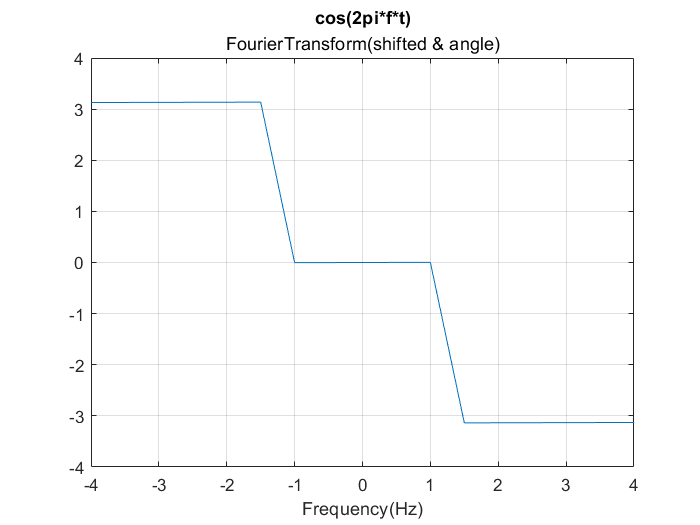


plot(fFft, angle(yFftshift))
xlim([-4 4])
grid on
title cos(2pi*f*t) FourierTransform(shifted & angle)
xlabel Frequency(Hz)

    Q4:


$$x(t)=\cos(2\pi f_0t)\\
\Longrightarrow \mathcal F\left\{x(t)\right\}=\int_{-\infty}^{+\infty}\cos(2\pi f_0t)e^{-j2\pi ft}dt\\
=\int_{-\infty}^{+\infty}\frac 12 \left(e^{-j2\pi f_0t}+e^{j2\pi f_0t}\right)e^{-j2\pi ft}dt\\
=\frac{1}{2}\int_{-\infty}^{+\infty}\left(e^{-j2\pi f_0t}e^{-j2\pi ft}+e^{j2\pi f_0t}e^{-j2\pi ft}\right)dt\\
=\frac{1}{2}\int_{-\infty}^{+\infty}\left(e^{-j2\pi t\left(f_0+f\right)}+e^{-j2\pi t\left(f-f_0\right)}\right)dt\\
=\frac{1}{2}\left(\int_{-\infty}^{+\infty}\left(e^{-j2\pi t(f_0+f)}\right)dt+\int_{-\infty}^{+\infty}\left(e^{-j2\pi t(f-f_0)}\right)\right) dt=\\\left.\left.\frac{1}{2}\right[\delta(f-f_0) + \delta(f+f_0) \right]$$


this shows that fourier transform of cos must have 2 dirac functions at both sides of 0 in distanse of f0. we did f0 = 0. Therefore the results of plots are as same as what we get from theory.

PART2:

    Q1: First we load data into our workspace and then we create new dataframe from indexing loaded data. finally we plot data.

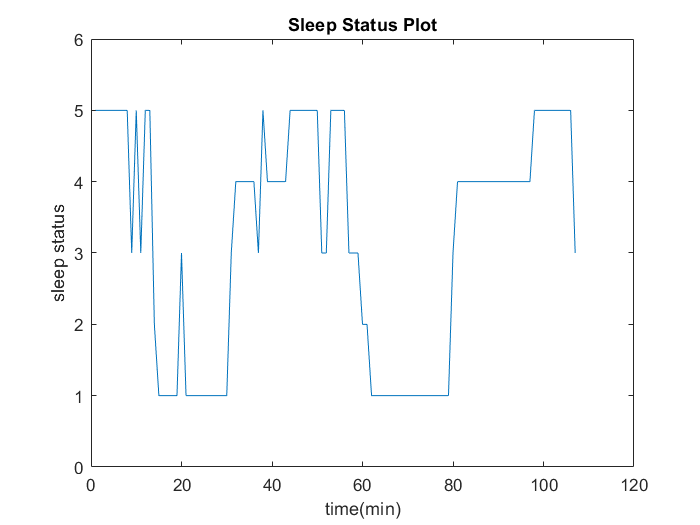

load("data.mat");
sleep_characters = ["qt", "qh", "tr", "al", "ah", "aw"];
sleep_dataframe = zeros(1,107);

for i = 1:numel(sleep_characters)
    sleep_dataframe(data == sleep_characters(i)) = i;
end

plot(sleep_dataframe)
title ("Sleep Status Plot")
ylim([0 6])
xlabel time(min)
ylabel ("sleep status")

we observe that in first half of sleep time, sleep staus is not stable in particular status. but second half we have much stabality in sleep status.

    Q2: 

s_f = 60;
f_axis = linspace(-s_f/2, s_f/2, numel(sleep_dataframe));
sleep_fft_shift = fftshift(fft(sleep_dataframe));

    Q3:

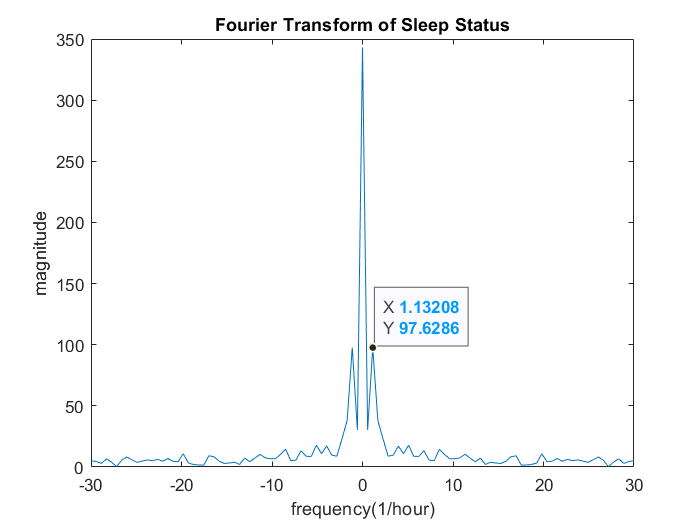

plot(f_axis, abs(sleep_fft_shift))
title ("Fourier Transform of Sleep Status")
xlabel("frequency(1/hour)")
ylabel("magnitude")

ax = gca;
chart = ax.Children(1);
datatip(chart,1.132,97.63);

    Q4: Accordig to plot above, we have peak at frequency = 1.132 (1/hour). This means when we transformed the signal of data to Fourier environment to get basic priodic functions(sin, cos, dc), we observe that the main periodic function(ignoring noises) that constructs the signal of data, has mentioned frequency. Therefore at each hour, 1.132 times cycle of kid's sleep completes and priod of sleep cycle of kid is 1 / 1.132 (hour) = 53 min;

    Q5:

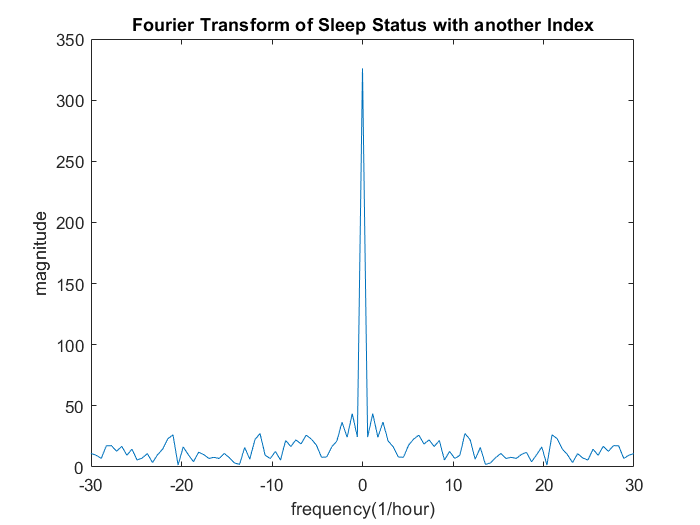

indexes = [3, 5, 6, 4, 1, 2];
new_sleep_dataframe = zeros(1,107);

for i = 1:numel(sleep_characters)
    new_sleep_dataframe(data == sleep_characters(i)) = indexes(i);
end

new_sleep_fft_shift = fftshift(fft(new_sleep_dataframe));

plot(f_axis, abs(new_sleep_fft_shift))
title ("Fourier Transform of Sleep Status with another Index")
xlabel("frequency(1/hour)")
ylabel("magnitude")

    This shows that we don't have apparent peak on plot and we have too mush noises. so we cannot analyze

    Q6:

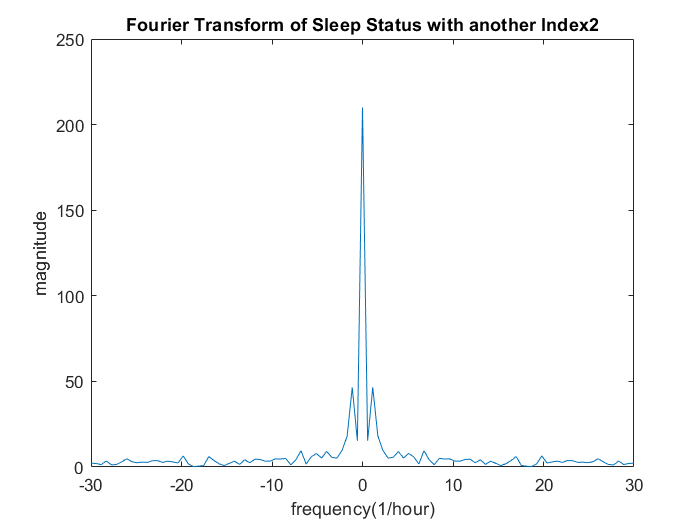

indexes2 = [1, 1, 2, 2, 3, 3];
new_sleep_dataframe2 = zeros(1,107);

for i = 1:numel(sleep_characters)
    new_sleep_dataframe2(data == sleep_characters(i)) = indexes2(i);
end

new_sleep_fft_shift2 = fftshift(fft(new_sleep_dataframe2));

plot(f_axis, abs(new_sleep_fft_shift2))
title ("Fourier Transform of Sleep Status with another Index2")
xlabel("frequency(1/hour)")
ylabel("magnitude")

    the results are the same as Q4, because the order of states are approximately the same and we just merge some states that are close. In another word we decreased resolution of data but we didn't change the whole order.

PART3:

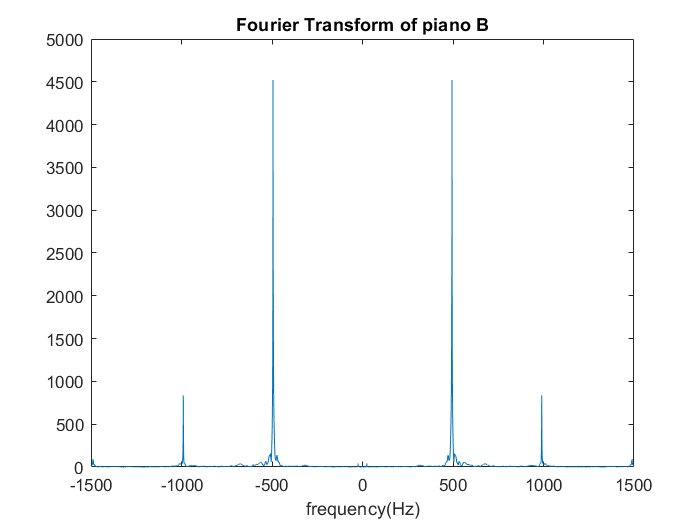

[B_signal, B_fs] = audioread("piano_B.mp3");
[G_signal, G_fs] = audioread("piano_G.mp3");

B_f_axis = linspace(-B_fs/2, B_fs/2, numel(B_signal));
G_f_axis = linspace(-G_fs/2, G_fs/2, numel(G_signal));

B_fft_shift = fftshift(fft(B_signal));
G_fft_shift = fftshift(fft(G_signal));

plot(B_f_axis, abs(B_fft_shift));
title("Fourier Transform of piano B")
xlabel("frequency(Hz)")
xlim([-1500 1500])

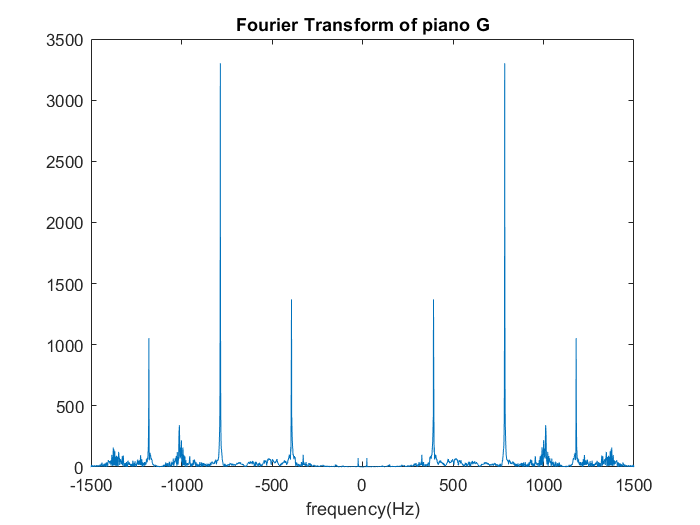


plot(G_f_axis, abs(G_fft_shift));
title("Fourier Transform of piano G")
xlabel("frequency(Hz)")
xlim([-1500 1500])

sound(B_signal, B_fs);

sound(G_signal, G_fs);

After we play these notes, we observe that  note B has lower pitch than note G. this maches with what we get form results of plots. According to plots above, note B is made of a few priodic signals with lower frequencies than note G( as we can see the dirac functions in B plot  happen in lower frequencies. but dirac functions in G plot happen in higher frequencies). Also we know that note B has frequecy about 493 Hz(between octave C4 and C5) and note G has frequecy about 784 Hz(between octave C5 and C6). this numbers cac get frem plots above as we can see the main dirac function in pot B happpens at about 500Hz, and main dirac function in pot G happpens at about 800Hz.